# SiSy HS20 Chapter 4 : AD-DA conversion

## Question 4-1

 (a) Start a new Matlab script, and define two cosine signals x1(t) and x2(t) with equal amplitude and frequencies of 1kHz und 7KHz.  Use for this definition a time vector with fine resolution, such that:      tstep $\le$ min{Period)} /100

(b) Define now in your Matlab script the corresponding discrete signals x1[n] and x2[n], that would result after sampling x1(t) and x2(t)  with a sampling frequency Fs =  8kHz. 

Hint: you can define the discrete signals based on a new „rough“ time vector with tstep=1/8kHz, or you can pick on x1(t) and x2(t) only the points left after the sampling. 

(c) Prepare in Matlab plots of the “time continuous” signals x1(t) and x2(t) and of the time discrete signals x1[n] and x2[n] . 

Hint: in order to better visualize the continuous and discrete characteristics of the signals, use the commands *plot()* and *stem()*. 

(d) After the sampling, can you still distinguish the frequency of the discrete signals x1[n] and x2[n] ? If these were unknown signals at the input of an ADC, which frequency would you suppose for them, when observing the signals at the output of the ADC? Which of these two signals has been distorted by the aliasing effect?

(e) In your Matlab script (without anti-aliasing filter), which Fs would be necessary to correctly sample x1(t) and x2(t). Verify your answer with a plot. 

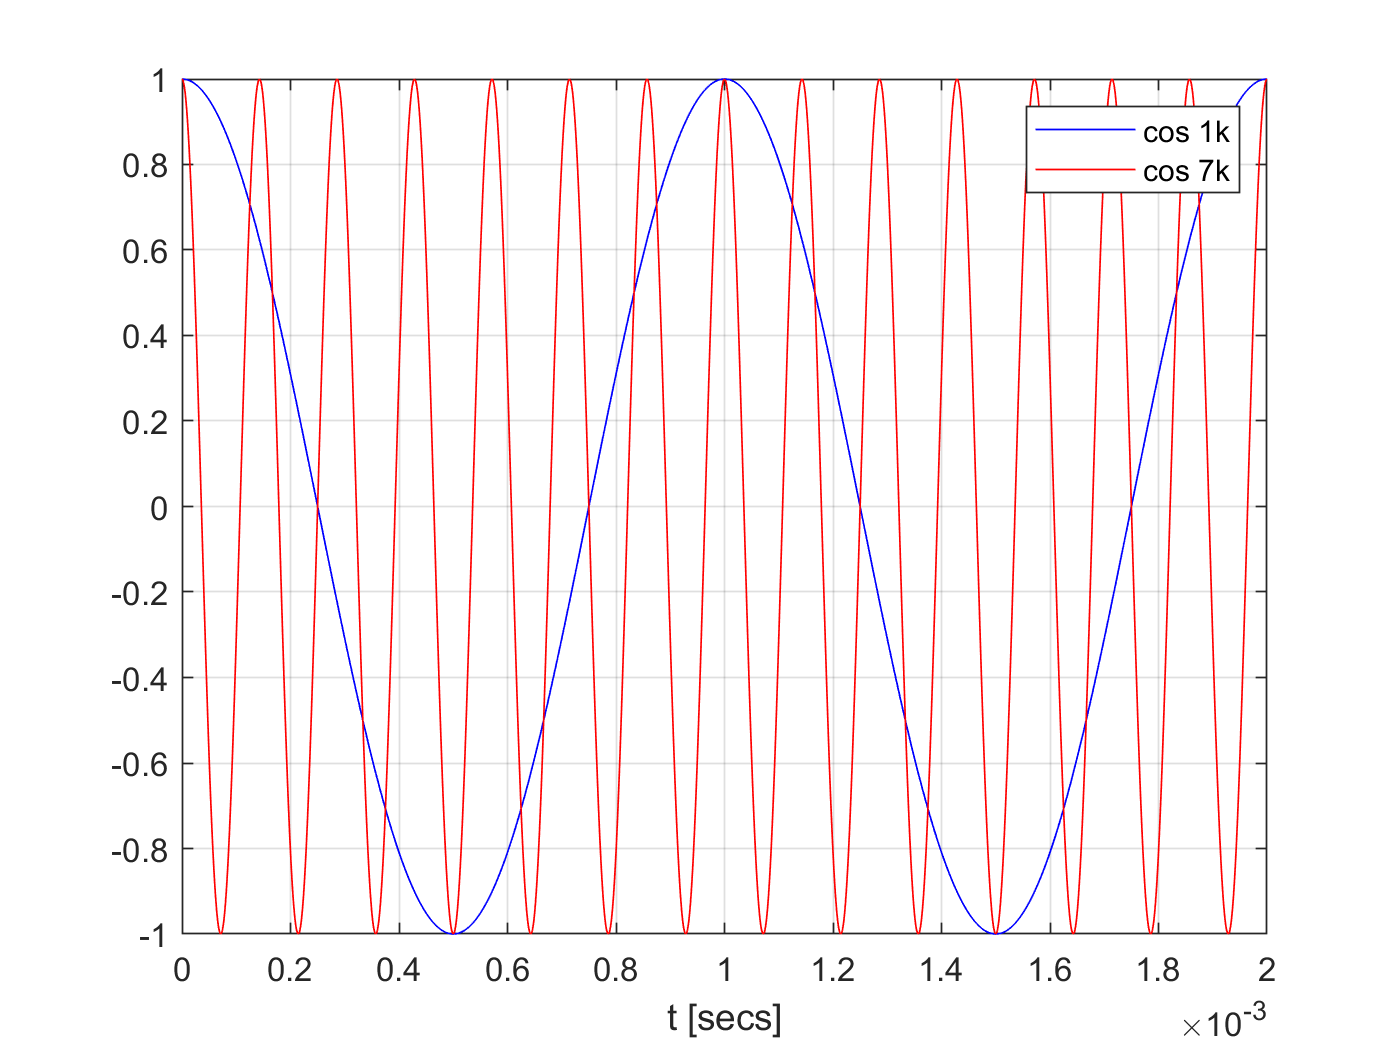

clear all, close all, clc;

% PARAMETERS
f1 = 1e3;
f2 = 7e3;
Fs = 8e3;

% Approximation of a time continuous signal
% time vector with a fine resolution
tstep_fine = (1/max(f1,f2))/100;
t_fine = 0:tstep_fine:2/min(f1,f2);

x1_t = cos(2*pi*f1*t_fine);
x2_t = cos(2*pi*f2*t_fine);

figure(1)
plot(t_fine,x1_t,'b',t_fine,x2_t,'r'),grid on, hold on
    legend({'cos 1k','cos 7k'}), xlabel('t [secs]')

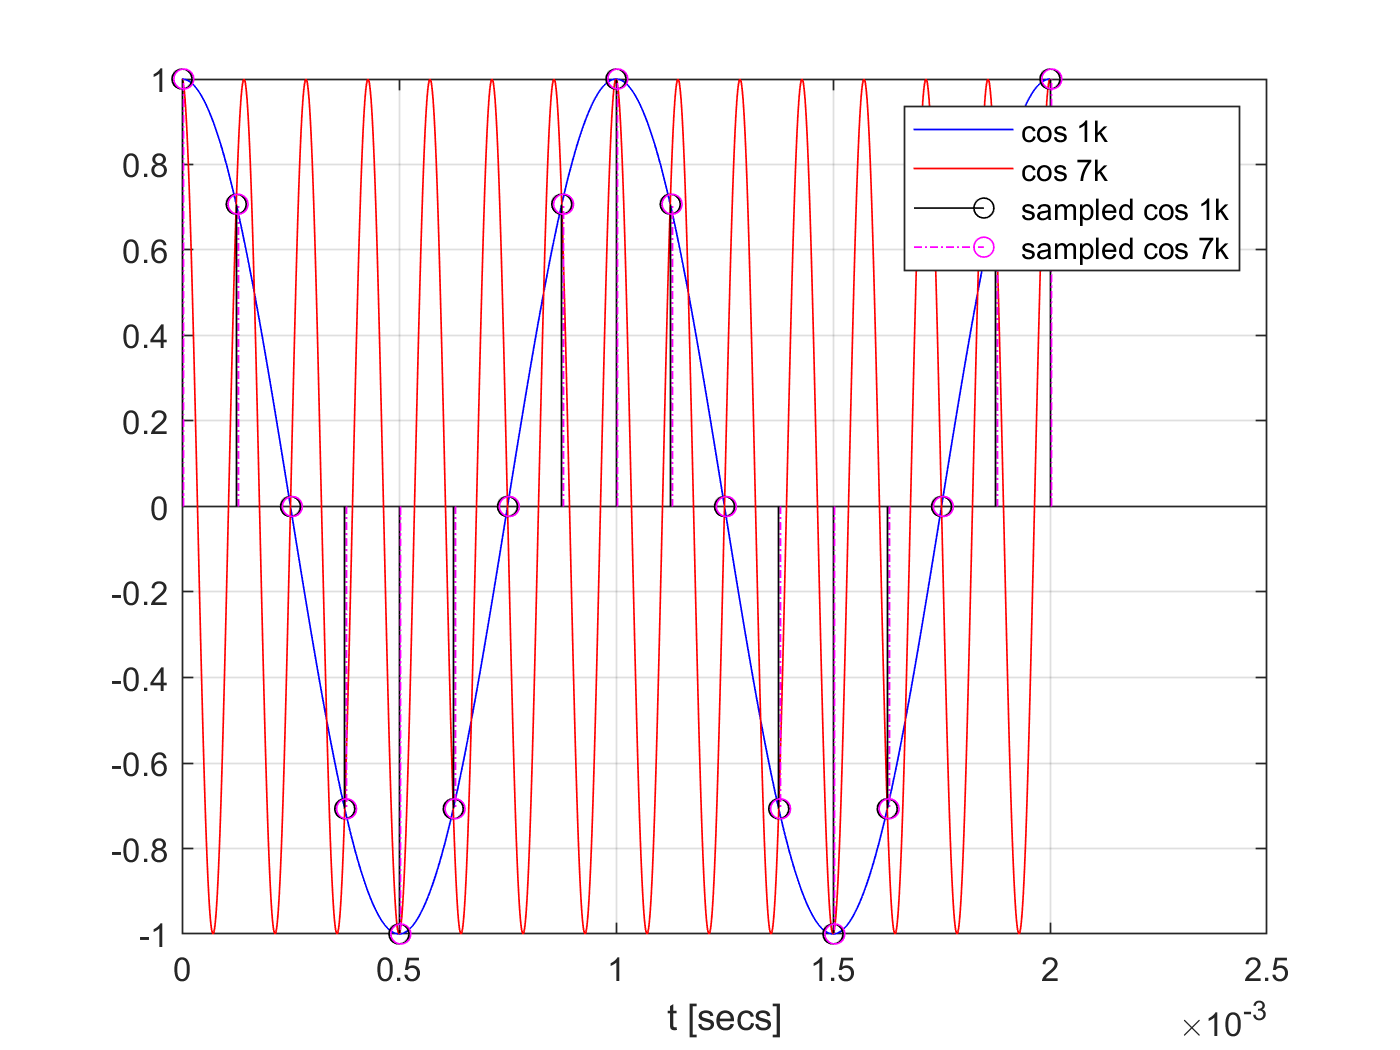


% Define the sampled signals
% time vector with a coarse resolution (Ts)
Ts = 1/Fs;   % tstep_coarse
t_coarse = 0:Ts:2/min(f1,f2);

x1_n = cos(2*pi*f1*t_coarse);
x2_n = cos(2*pi*f2*t_coarse);

figure(1)
delF= Ts/30;       % for visualisation, so plots do not fully overlap
stem(t_coarse,x1_n,'k')
stem(t_coarse+delF,x2_n,'m-.'), hold off, xlabel('t [secs]')
    legend({'cos 1k','cos 7k','sampled cos 1k','sampled cos 7k'})

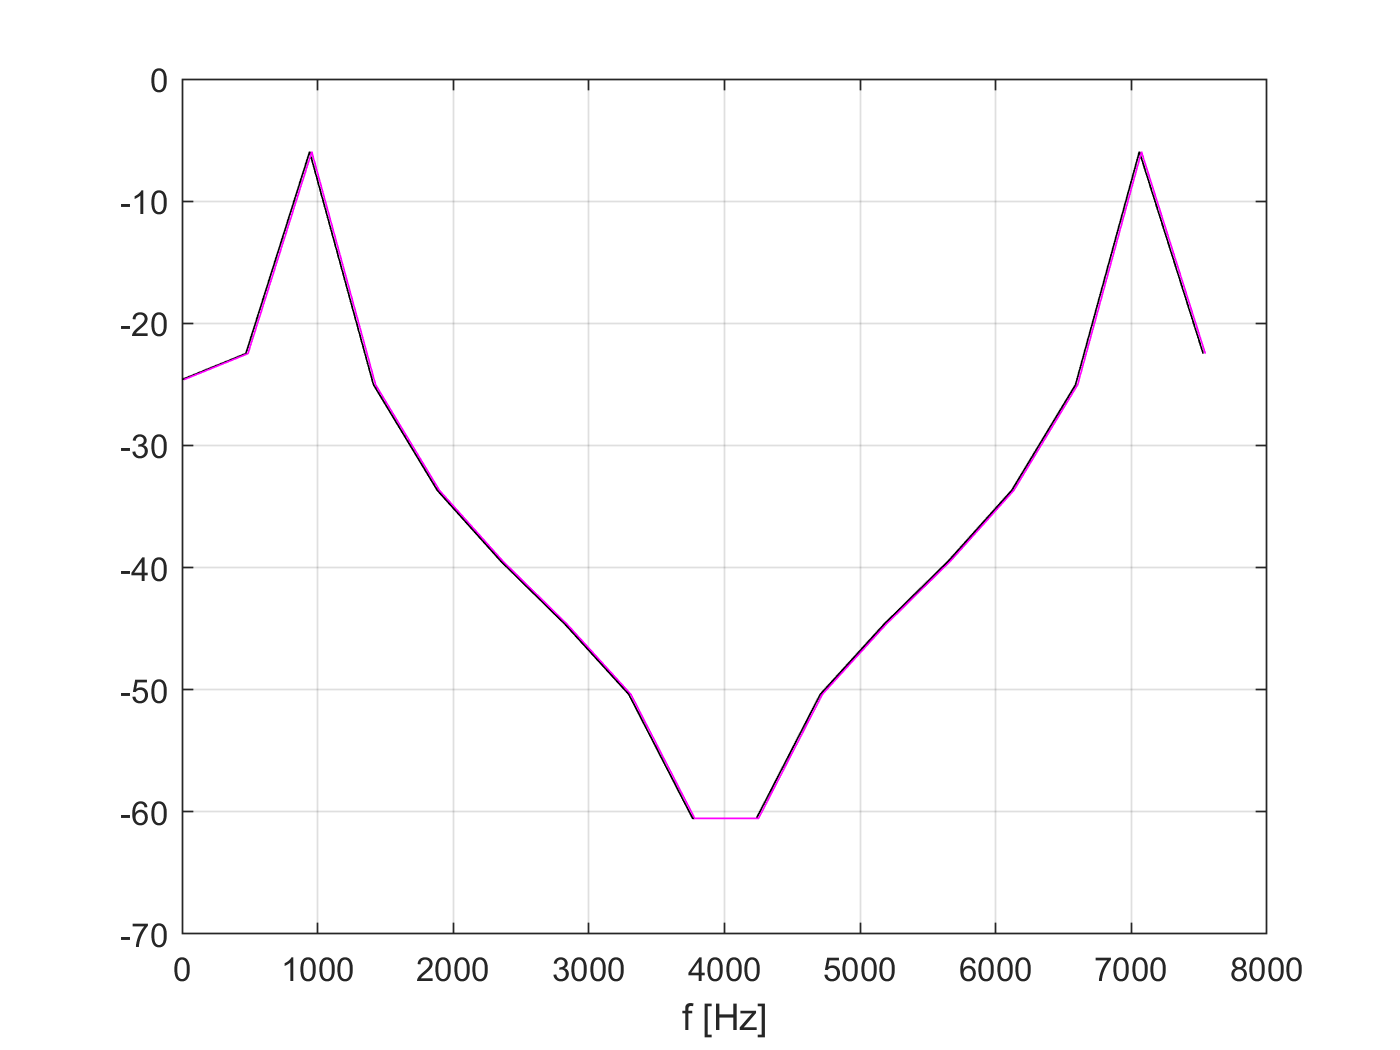

% Check the corresponding spectra

N = length(t_coarse);
aux = 0:1:N-1;
f_coarse = Fs/N * aux;

X1_f = (1/N)*fft(x1_n);
X2_f = (1/N)*fft(x2_n);

figure(2)
delF= Fs/(N*30);       % for visualisation in plot
plot(f_coarse, db(X1_f),'k'), grid on, hold on
plot(f_coarse+delF, db(X2_f),'m'), hold off, xlabel('f [Hz]')

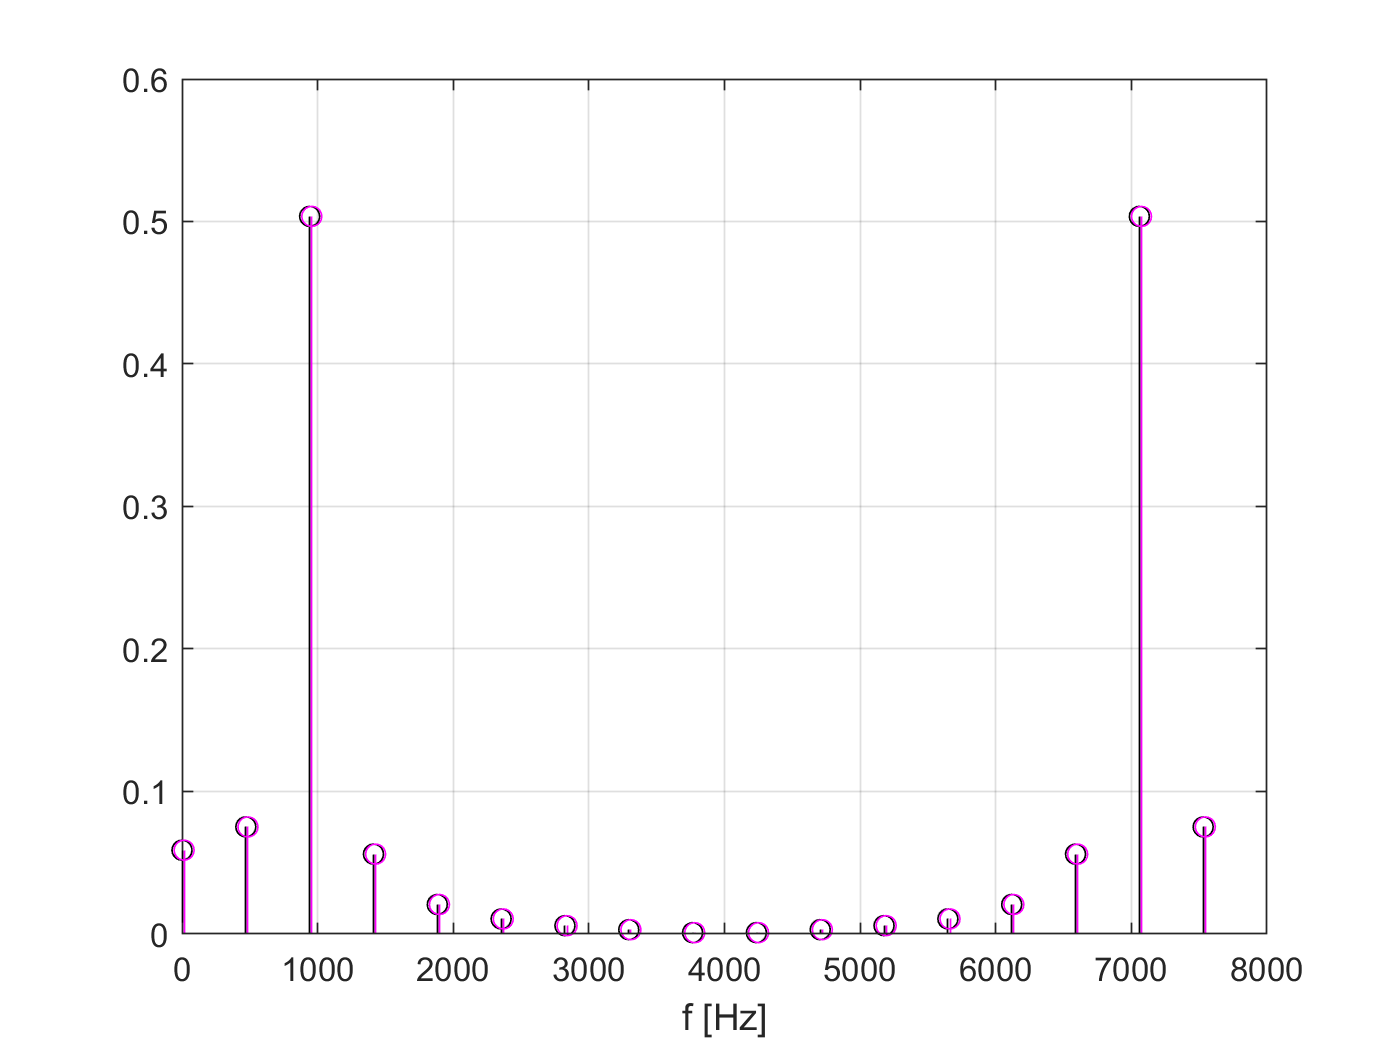


figure(3)
stem(f_coarse, abs(X1_f),'k'), grid on, hold on
stem(f_coarse+delF, abs(X2_f),'m'), hold off, xlabel('f [Hz]')

% check why you are not getting a single peak at 1kHz and 7kHz (spectrum leakage)
fstep = Fs/N             % spectrum resolution

fstep = 470.5882

f1/fstep                 % closest X[k] coefficient

ans = 2.1250

## Question 4-2

Draw a series of sketches in time and frequency domain representing the signal x1(t) from the previous exercise along the AD-DA chain.  

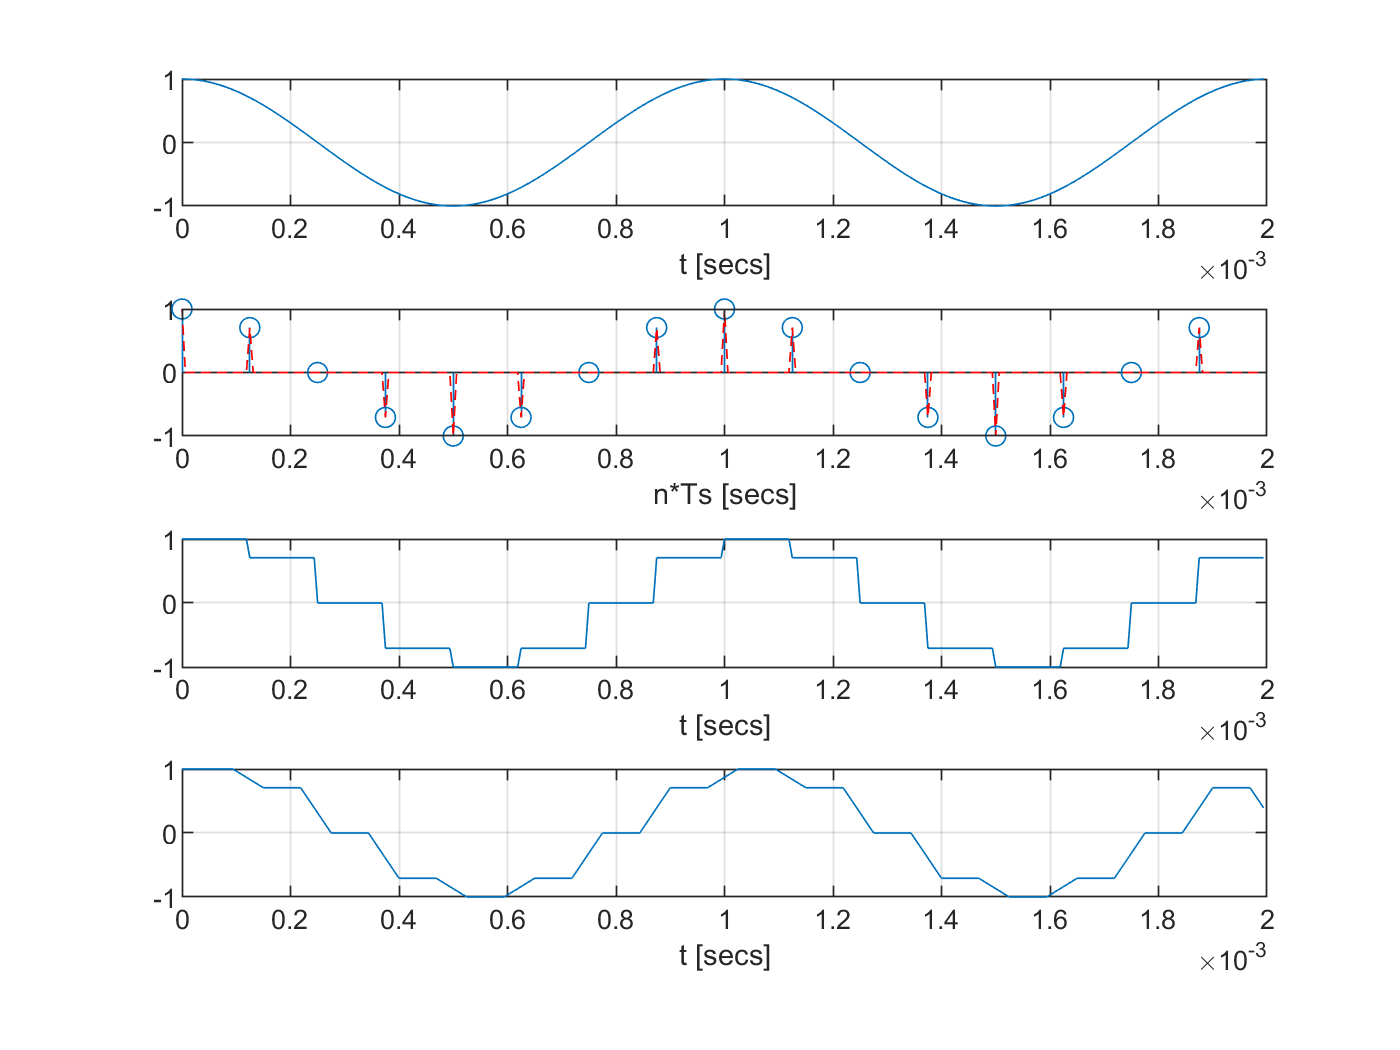

% The detailed sketches time vs freq domain are drawn on paper and measured in Lab-4
% the numerical calculations only show the 1st nyquist zone, and therefore do not show explicitly the periodic spectrum.
%
% Here below, simulate time domain steps:

% (1) Original signal ("continuous") :                  x1(t)
% (2) After ADC : discrete sampled with Fs = 8kHz :     x1[n]
% (3) After DAC : with ZOH same Fs :                    x1_zoh(t)
% (4) After LPF : anti-imaging or reconstruction :      x1_rec(t)

clear all, close all, clc;
% PARAMETERS : redefine for simpler calculation (with integer ratio Ts/t_step_fine)
N = 16;
aux = 0:1:N-1;

Fs = 8e3;
Ts = 1/Fs;

% Define continuous time vector and continuous signal
M = 20 ;        % integer factor between coarse and fine time step
tstep_fine = Ts/M;
t = tstep_fine*[0:1:M*N-1];
x1_t = cos(2*pi*1e3*t);

% Define discrete time vector and discrete signal
nTs = Ts*aux;
x1_n = cos(2*pi*1e3*nTs);  % equivalent to x1_n = x1_t(1:20:end)

% Define ZOH impulse response with width of 1 DAC-Symbol
zoh_imp = ones(1,M);                % The impulse response of the ZOH is a square with M points
x1_up = upsample(x1_n,M);           % Before the convolution need to get back to a "continuous" function (insert M-zeros between samples)
x1_zoh = conv(x1_up,zoh_imp);       % Convolution with ZOH impulse response
x1_rec = smooth(x1_zoh,10);         % This LPF is a moving-average, with default span=5. Vary span to test effect.


figure(4)
subplot(411), plot(t,x1_t), grid on, xlabel('t [secs]')
subplot(412), stem(nTs,x1_n), grid on, hold on, xlabel('n*Ts [secs]')
              plot(t,x1_up,'r--'), hold off
subplot(413), plot(t,x1_zoh(1:length(t))), grid on, xlabel('t [secs]')              
subplot(414), plot(t,x1_rec(1:length(t))), grid on, xlabel('t [secs]')  

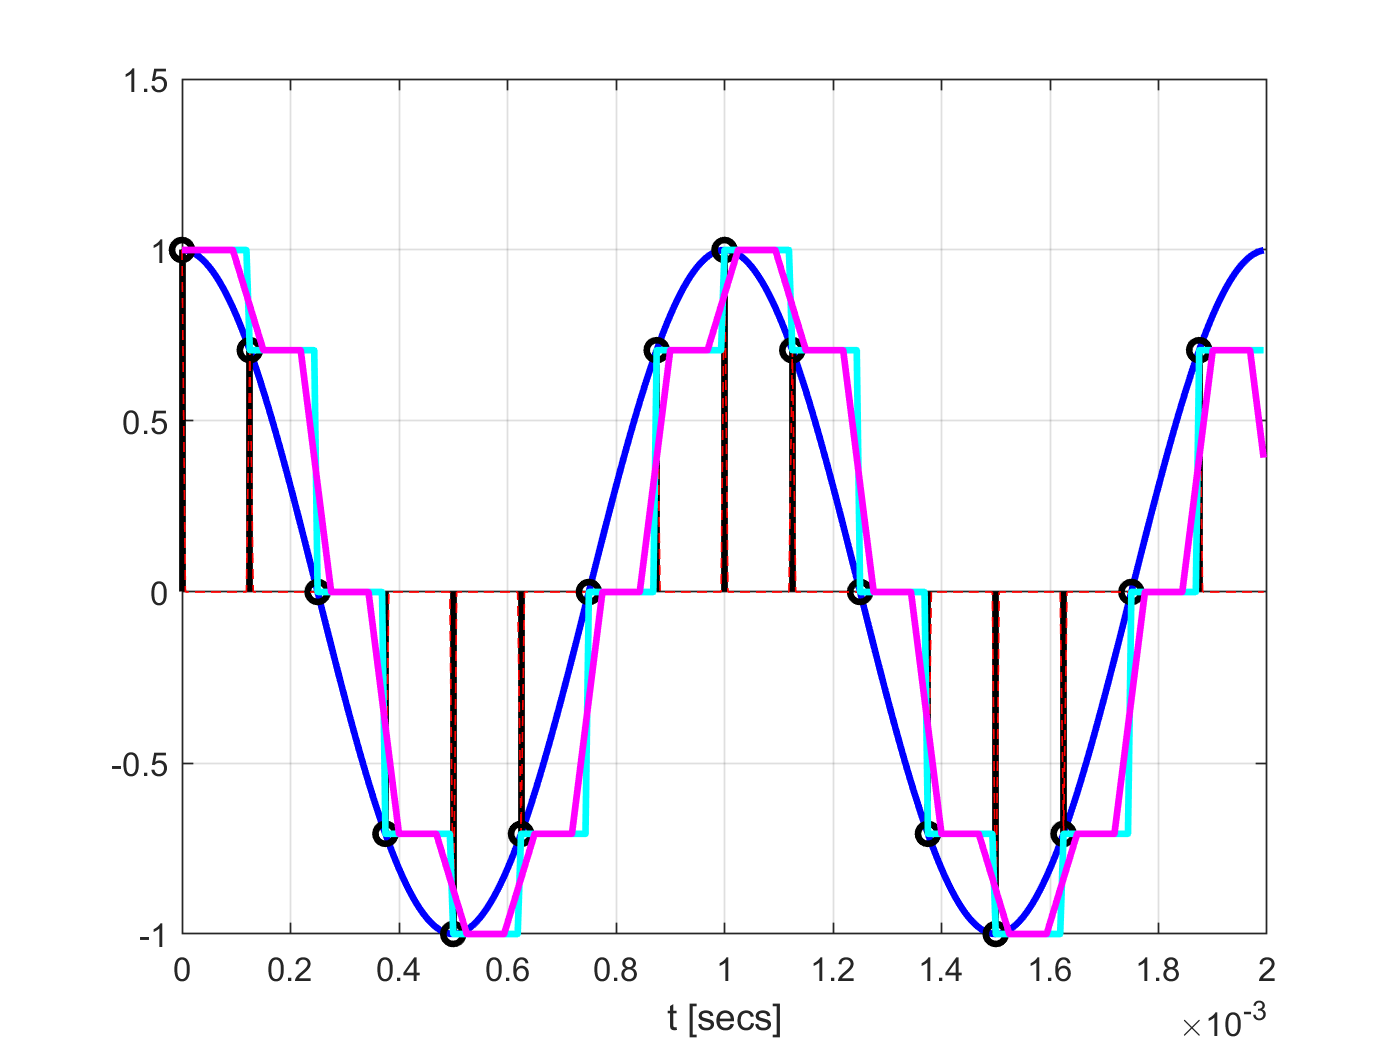

figure(5)
plot(t,x1_t,'b','LineWidth',2), grid on, hold on,   % original
stem(nTs,x1_n,'k','LineWidth',2)                                  % after ADC
plot(t,x1_up,'r--')                                 % upsampled
plot(t,x1_zoh(1:length(t)),'c','LineWidth',2)                     % after ZOH
plot(t,x1_rec(1:length(t)),'m','LineWidth',2)       % after LPF
    hold off, xlabel('t [secs]')  

## Understanding + experimenting with quantisation effect

Consider the input signal has been normalised to fit a value-range [0;1)

This range is then quantified with Q-Bits

Then vary Q and check the influence in the output signal in time and frequency domain.

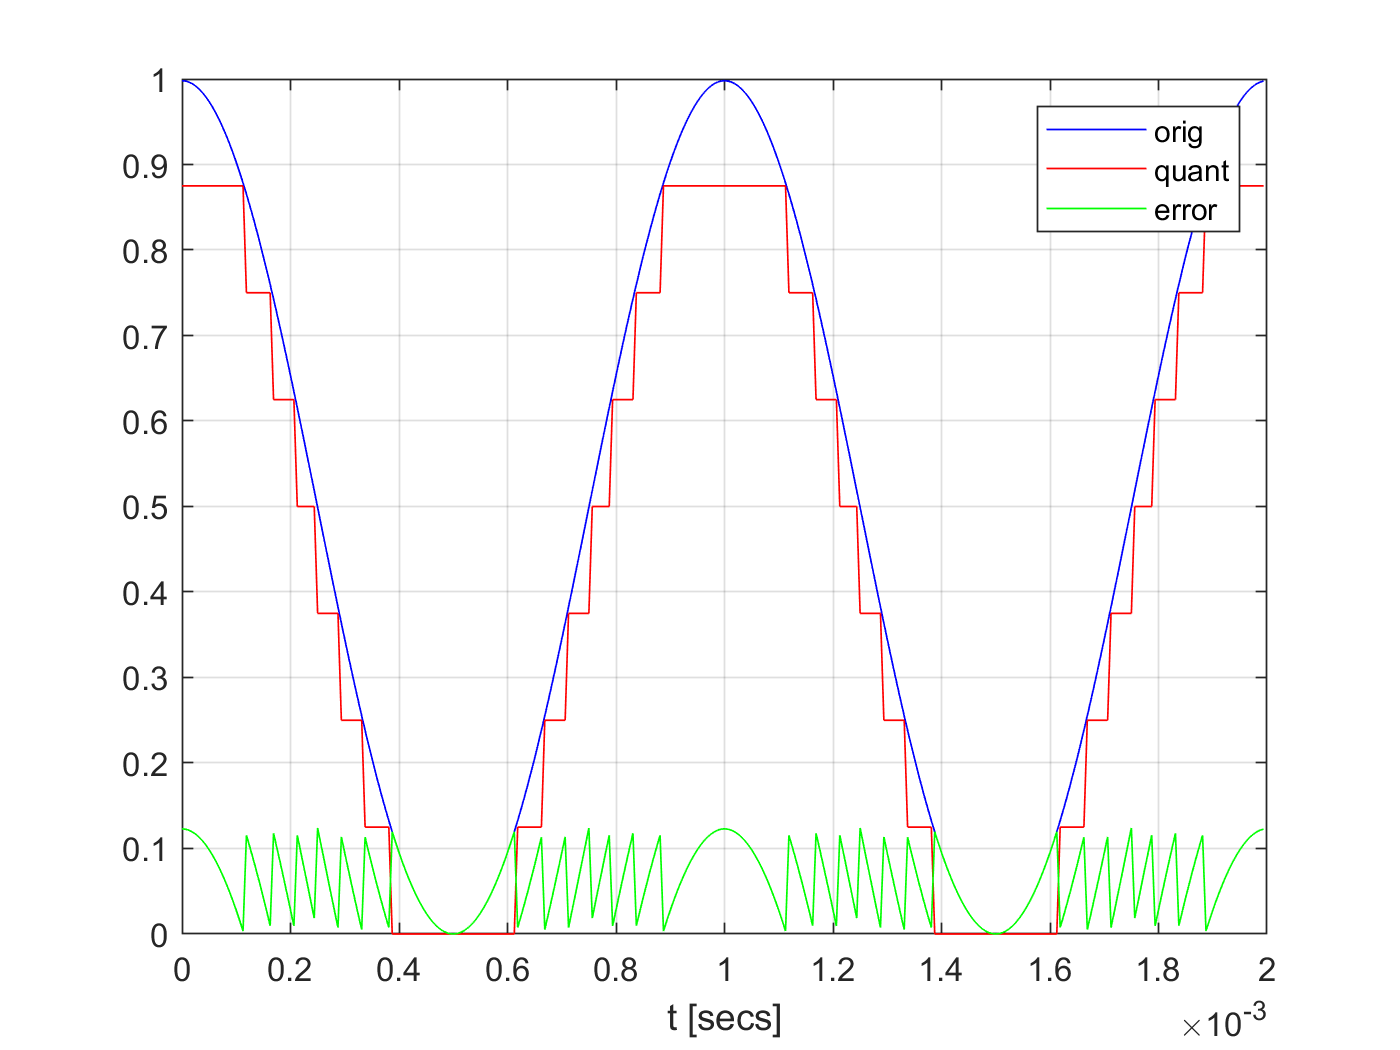

y_t = 0.499*(1 + cos(2*pi*1e3*t));   % 0.01 margin to avoid value = +1 (and associated spike after quantisation)

Q = 3;
y_quant = floor(y_t*2^Q)/2^Q;
e_quant = y_t - y_quant;

figure(6)
plot(t,y_t,'b',t,y_quant,'r',t,e_quant,'g'), grid on, xlabel('t [secs]')
    ylim([0 1])    % normalised range
    legend({'orig','quant','error'})

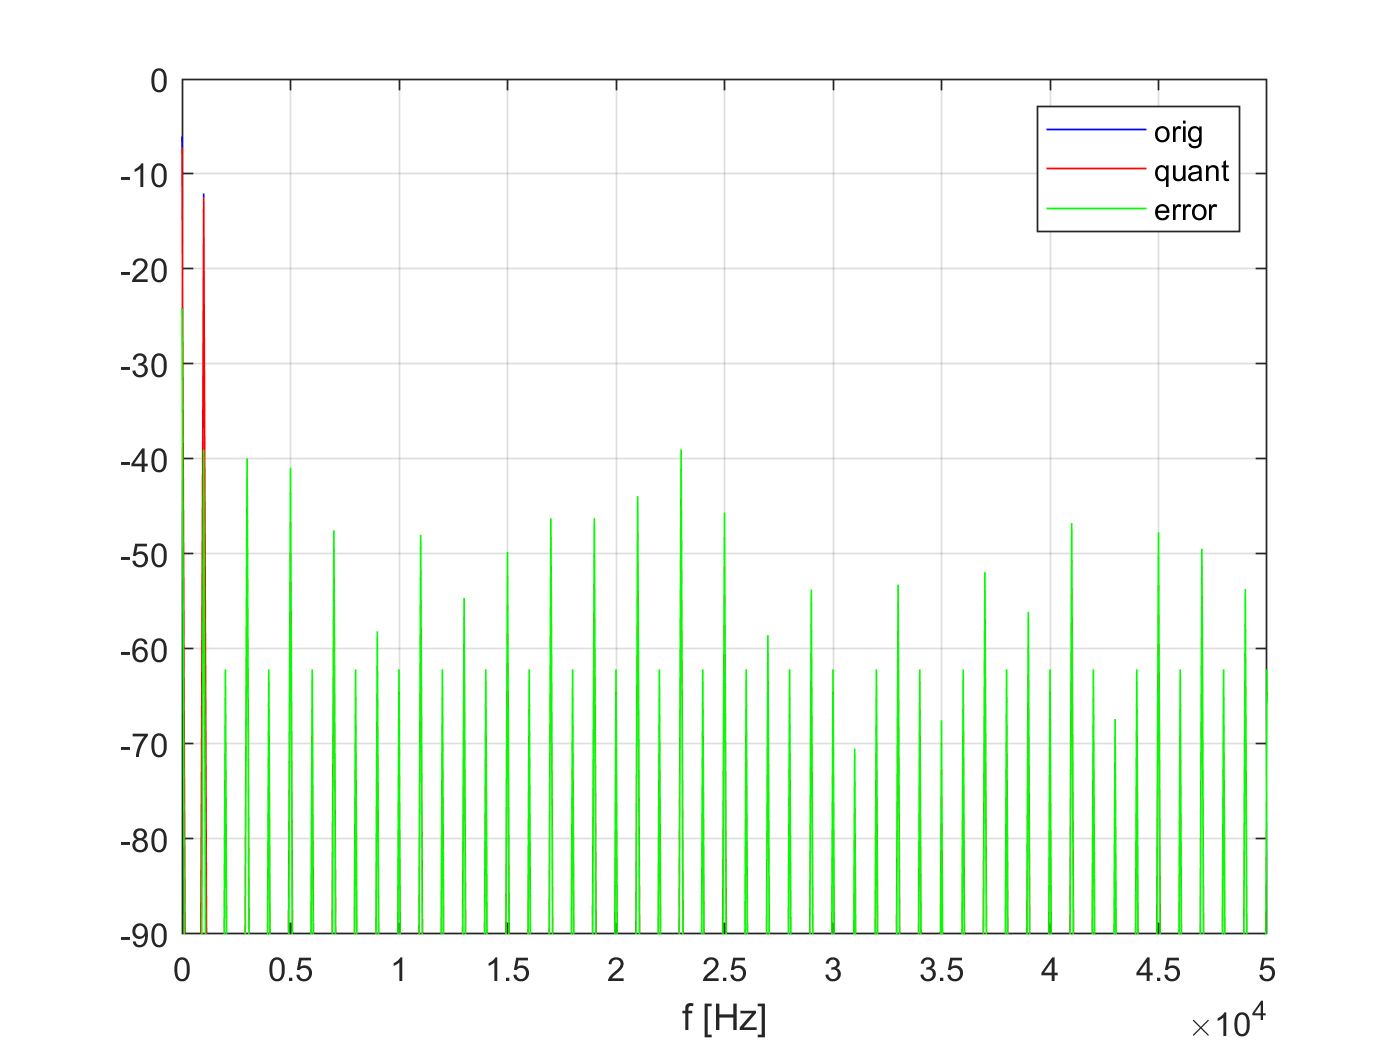

% check spectrum
N_fine = length(t);         % Above defined N for vector sampled with coarse Fs, therefore calling here fine
Fs_fine = 1/(t(2));
fvec_fine = (Fs_fine/N_fine)*[0:1:N_fine-1];

Y_f      = (1/N_fine)*fft(y_t);
Yquant_f = (1/N_fine)*fft(y_quant);        
Equant_f = (1/N_fine)*fft(e_quant);

   
Y_f_dB      = db(Y_f);
Yquant_f_dB = db(Yquant_f + eps);        % added epslon cause 0-value gives -Inf in dB (and do not plot...)
Equant_f_dB = db(Equant_f);
      
figure(7)
plot(fvec_fine,Y_f_dB,'b',fvec_fine,Yquant_f_dB,'r',fvec_fine,Equant_f_dB,'g'), grid on, 
    xlabel('f [Hz]'), xlim([0 50e3]), ylim([-90 0])
    legend({'orig','quant','error'})  

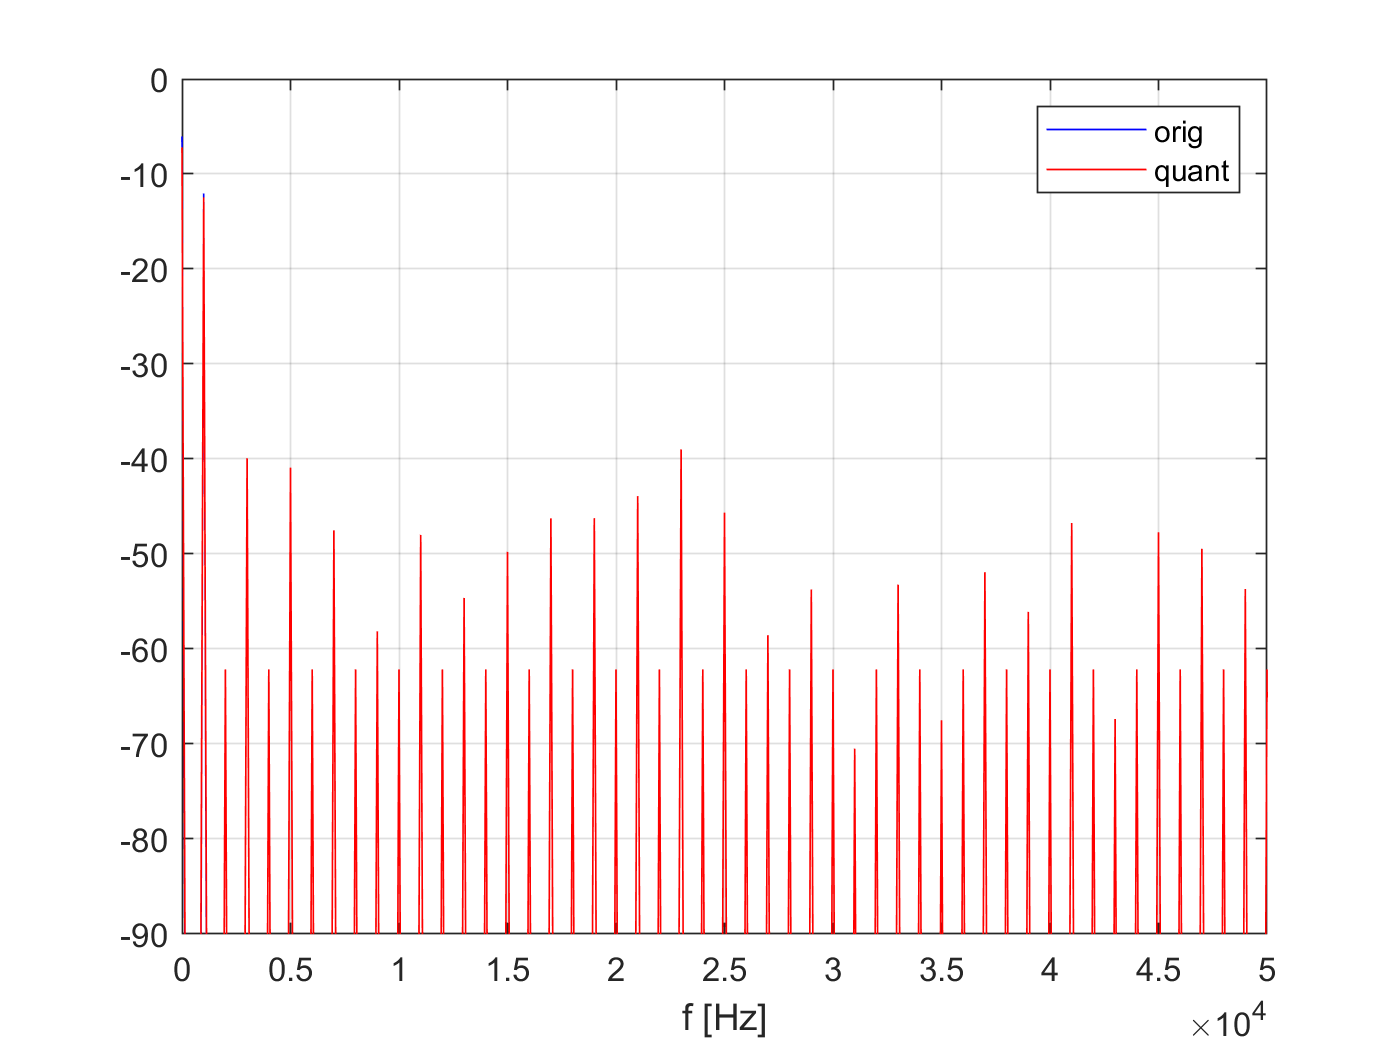

figure(8)  % repeat plot but only orig & quant (without the plot of error) to double-check SFDR
plot(fvec_fine,Y_f_dB,'b',fvec_fine,Yquant_f_dB,'r'), grid on,             
    xlabel('f [Hz]'), xlim([0 50e3]), ylim([-90 0])
    legend({'orig','quant'})     